## Get Info about Source and Hardware

source = getselectedsource(camL); source.FrameRate Use the SupportedFormats to specify the 'format' of videoinput object above info = imaqhwinfo('macvideo') info.DeviceInfo.SupportedFormats

## set up video streams

videoL = videoinput('winvideo', 2);
videoL.FrameGrabInterval = 1;
videoL.FramesPerTrigger = 1;
videoL.LoggingMode = 'disk';
videoL.ReturnedColorSpace = 'RGB';
videoL.TimeOut = Inf;
videoL.TriggerRepeat = Inf;

videoR = videoinput('winvideo', 3);
videoR.FrameGrabInterval = 1;
videoR.FramesPerTrigger = 1;
videoR.LoggingMode = 'disk';
videoR.ReturnedColorSpace = 'RGB';
videoR.TimeOut = Inf;
videoR.TriggerRepeat = Inf;

## construct VideoWriter object and set DiskLogger property

writeL = VideoWriter('test_left.avi');
writeL.Quality = 25;
writeL.FrameRate = 30; % 30
videoL.DiskLogger = writeL;

writeR = VideoWriter('test_right.avi');
writeR.Quality = 25;
writeR.FrameRate = 30; % 30
videoR.DiskLogger = writeR;

## preview stream of image frames

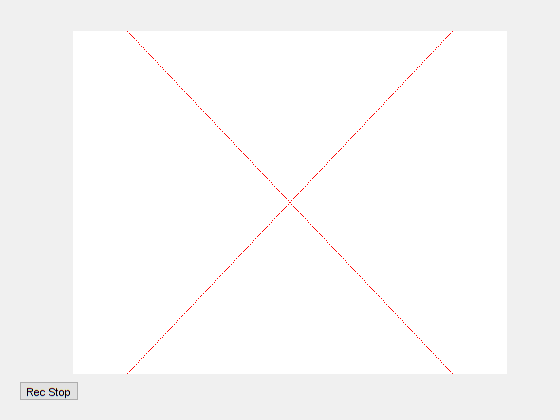

% create GUI
fig = figure('Name', 'Video Recording Preview (left only)');
uicontrol('String', 'Rec Stop', 'Callback', 'close(fig); delete(fig);');

% create image object for previewing
vidRes = videoL.VideoResolution;
nBands = videoL.NumberOfBands;
hImage = image(zeros(vidRes(2), vidRes(1), nBands));
preview(videoL, hImage);

## record video feeds

% start video streams
tic % start stopwatch timer

start(videoL);
start(videoR);

%pause(10);

% continue recording until figure gets closed
uiwait(fig)

% stop video
stop(videoL);
stop(videoR);

wait(videoL)
wait(videoR)

videoL.FramesAcquired

ans = 9505

videoL.DiskLoggerFrameCount

ans = 9505


videoR.FramesAcquired

ans = 9493

videoR.DiskLoggerFrameCount

ans = 9493

## process attained files

output = EqualFrames('test_left.avi', 'test_right.avi');

     2

     2

     3

     3

     4

     4

     5

     5

     6

     6

     7

     7

     8

     8

     9

     9

    10

    10

    11

    11

    12

    12

    13

    13

    14

    14

    15

    15

    16

    16

    17

    17

    18

    18

    19

    19

    20

    20

    21

    21

    22

    22

    23

    23

    24

    24

    25

    25

    26

    26

    27

    27

    28

    28

    29

    29

    30

    30

    31

    31

    32

    32

    33

    33

    34

    34

    35

    35

    36

    36

    37

    37

    38

    38

    39

    39

    40

    40

    41

    41

    42

    42

    43

    43

    44

    44

    45

    45

    46

    46

    47

    47

    48

    48

    49

    49

    50

    50

    51

    51

    52

    52

    53

    53

    54

    54

    55

    55

    56

    56

    57

    57

    58

    58

    59

    59

    60

    60

    61

    61

    62

    62

    63

    63

    64




% compute actual frame rate
elapsedTime = toc; % stop stopwatch timer
framesaq = videoL.FramesAcquired;
actualfr = framesaq/elapsedTime;

% delete Object
delete(videoL);
delete(videoR);

## Change the Frame Rate to Orinial Value and save it to new video file

with the same timestamp

if output == 1
    ChangeFrameRate('corrected_video_1.avi', 'left', actualfr) % process videoL
    ChangeFrameRate('test_right.avi', 'right', actualfr) % process videoR
else
    ChangeFrameRate('test_left.avi', 'left', actualfr) % process videoL
    ChangeFrameRate('corrected_video_2.avi', 'right', actualfr) % process videoR
end

## change frame rate so that saved video is as long as recording

function output = EqualFrames(file1, file2)
    obj1 = VideoReader(file1);
    obj2 = VideoReader(file2);
    it1 = 1;
    it2 = 1;
    while hasFrame(obj1) || hasFrame(obj2)
        if hasFrame(obj1)
            readFrame(obj1);
            it1 = it1 +1;
        end
        if hasFrame(obj2)
            readFrame(obj2);
            it2 = it2 + 1;
        end
        disp(it1);
        disp(it2);
    end
    
    delete(obj1)
    delete(obj2)
    
    videoL = VideoReader(file1);
    videoR = VideoReader(file2);
    
    delta = abs(it1- it2);
    if it1 > it2
       % for video1 having more frames 
       write1 = VideoWriter(['corrected_video_1', '.avi']);

       % open Video Writer Object
       open(write1);
       
       for k = delta  : it1
           frame = readFrame(videoL);
           writeVideo(write1, frame);         
       end
       
       output = 1;
                 
    else it2 > it1
       % for video1 having more frames 
       write2 = VideoWriter(['corrected_video_2', '.avi']);

       % open Video Writer Object
       open(write2);
       
       for k = delta  : it2
           frame = readFrame(videoR);
           writeVideo(write2, frame);         
       end
       
       output = 2;
    end
end




function ChangeFrameRate(file, pos, actualfr)

% construct Video Objects
video = VideoReader(file);
write = VideoWriter(['ActualFR_', pos, '.avi']);
write.FrameRate = actualfr;

% open Video Writer Object
open(write);

% read video frames until the end of the file is reached
while hasFrame(video)
    frame = readFrame(video);
    writeVideo(write, frame)
    pause(1/video.FrameRate);
end

% Close Video Writer Object
close(write);
end